x0 = [0;0];

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.000000e+00    0.000e+00    2.000e+00
    1      13    7.753537e-01    0.000e+00    6.250e+00    1.768e-01
    2      18    6.519648e-01    0.000e+00    9.048e+00    1.679e-01
    3      21    5.543209e-01    0.000e+00    8.033e+00    1.203e-01
    4      24    2.985207e-01    0.000e+00    1.790e+00    9.328e-02
    5      27    2.653799e-01    0.000e+00    2.788e+00    5.723e-02
    6      30    1.897216e-01    0.000e+00    2.311e+00    1.147e-01
    7      33    1.513701e-01    0.000e+00    9.706e-01    5.764e-02
    8      36    1.153330e-01    0.000e+00    1.127e+00    8.169e-02
    9      39    1.198058e-01    0.000e+00    1.000e-01    1.522e-02
   10      42    8.910052e-02    0.000e+00    8.378e-01    8.301e-02
   11      45    6.771960e-02    0.000e+00    1.365e+00    7.149e-02
   12      48    6.437664e-02    0.000e+00    1

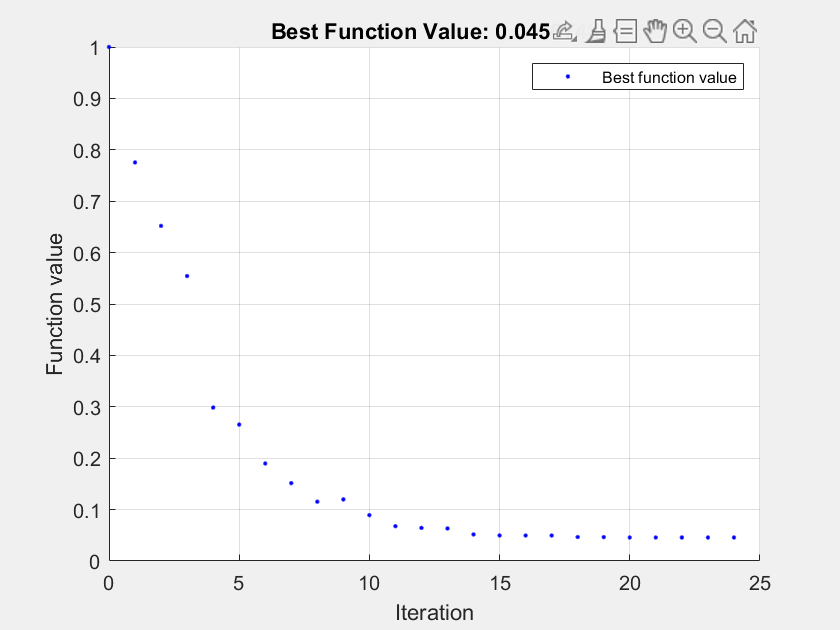


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% Set nondefault solver options
options = optimoptions("fmincon","Display","iter","PlotFcn",...
    "optimplotfvalconstr");

% Solve
[solution,objectiveValue] = fmincon(@objectiveFcn,x0,[],[],[],[],[],[],...
    @unitdisk,options);


% Clear variables
clearvars options

disp(solution)

    0.7864
    0.6177



disp(objectiveValue)

    0.0457



function f = objectiveFcn(optimInput)
% Example:
% Minimize Rosenbrock's function
% f = 100*(y - x^2)^2 + (1 - x)^2

% Edit the lines below with your calculation
x = optimInput(1);
y = optimInput(2);
f = 100*(y - x^2)^2 + (1 - x)^2;
end

function [c,ceq] = unitdisk(x)
c = x(1)^2 + x(2)^2 - 1;
ceq = [ ];
end

